In this onboarding you will build both a physical simscape model and a Linear Quadratic Regulator (LQR) controller for a cart-pole system

You will first construct the cart-pole as a physical system using Simscape Multibody. You will then develop a mathematical model of the system in MATLAB and use this model to design an LQR controller. Finally, you will implement the controller in Simulink and test it against the Simscape model.

The purpose of this project is not simply to make the pendulum balance. By the end, you should understand how a physical system is translated into a mathematical model and how that model is used to design a controller.

This is a diagram of the system:

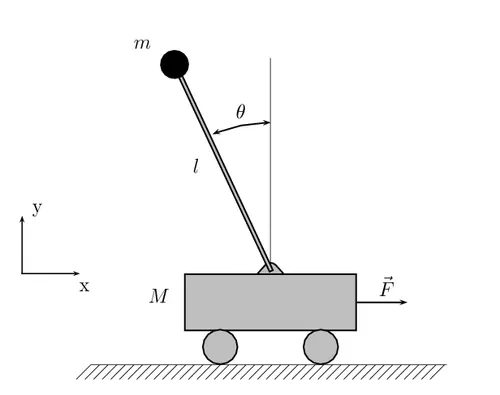

with these variable conventions:

the goal is to keep the inverted pendulum upright while controlling the position of the cart

The pendulum is inherently unstable. If the pendulum is displaced from its upright position, gravity causes it to fall. The controller must therefore continuously move the cart to keep the pendulum balanced.

### Task 1:

create a simulink model and add the required blocks:

you should set up these blocks in a way that allows the cart to move along the world x axis on the prismatic joint and allows the rod to rotate around the world y axis while attached to the cart. you will need to use Rigid Transform blocks to ensure the joints are oriented correctly and that the solids are positioned correctly

Then enable sensing for position and velocity for both the Prismatic and Revolute joints to ensure that the conventions are correct and it behaves as expected. if you set it up so the pendulum is initially balanced you wont see any movement, so try giving the pendulum some initial rotation just to verify things are set up.

Hint 1 contains the completed multibody if you cannot figure it out.

### Task 2:

now that we can measure the states of the system, we should compile those into a state vector:

x_vec = [x x_dot theta theta_dot]

Using the cart-pole diagram and the variable definitions above, derive the nonlinear equations of motion for the system.

Your equations should describe: x_ddot and theta_ddot

as functions of:

x_vec ie [x x_dot theta theta_dot] and the input F which is the force applied to the cart

note that they will not necessarily be the same as any you find online as our rod has a different moment of inertia to most that use a point mass or line mass

If you have taken a dynamics course this step should be self explanatory, if you have not, hint 2 goes in depth on the derivations 

Once you have these equations, implement them in matlab as a function:

function x_vec_dot = dynamics(x_vec, F)

make sure that all constants are the same as you have put into the simscape model and that you properly calculate the rods moment of inertia.

If you are struggling with this, hint 3 contains the completed dynamics

It is worth validating your model against the simscape one, this can be done programatically by using matlabs ode45 function, and comparing results, or just by putting that matlab function in a simulink function block and comparing resulting graphs. if they dont match, try to debug it yourself.